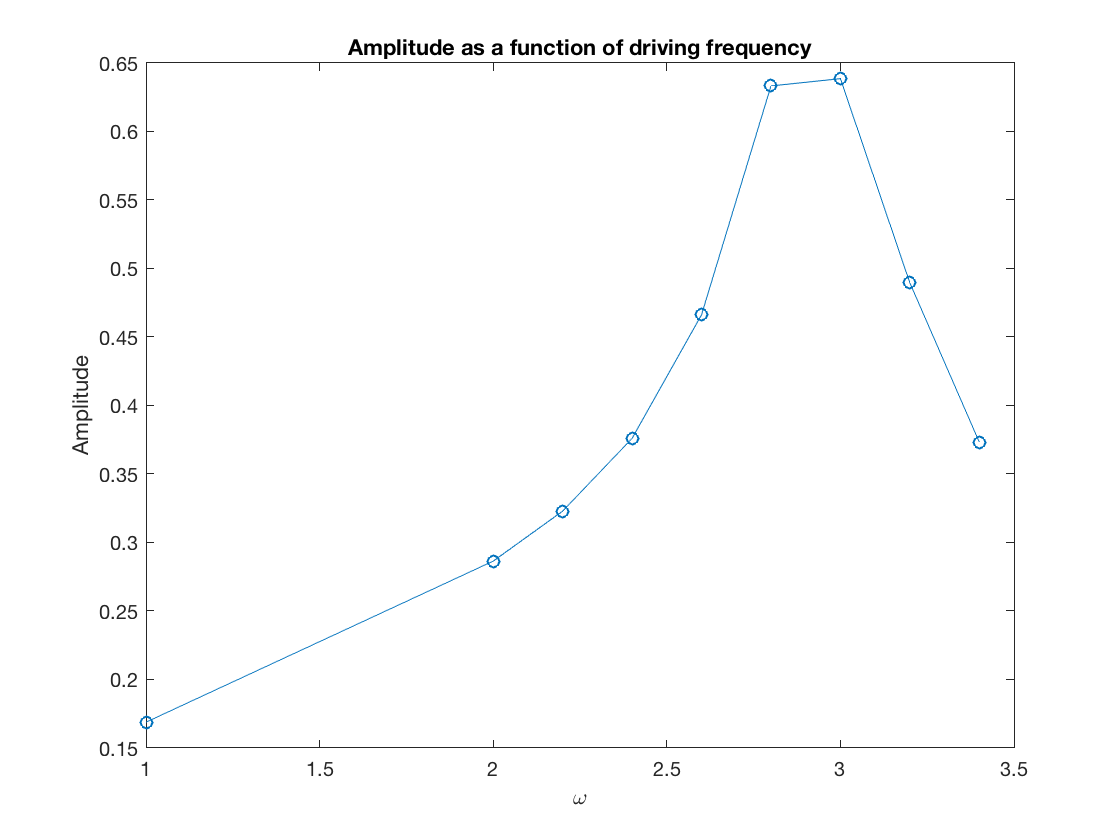

clc
clear all
g=9.81;
R=g/9;
thetad0=0;
theta0=0;
gamma=0.5;
ome=[1,2,2.2,2.4,2.6,2.8,3.0,3.2,3.4];
for i=1:length(ome)
     [t,w]=pendulum4(R,theta0,thetad0,gamma,ome(i));
     ind5 = find(w(:,2)>=0 & circshift(w(:,2), [-1 0]) <=0);
     A(i)=max(w(ind5,1));
     ind5=zeros;
end
plot(ome,A,'-o')
xlabel('\omega')
ylabel('Amplitude')
title('Amplitude as a function of driving frequency')

[Amax,nn]=max(A);
Amax

Amax = 0.6386

wmax=ome(nn)

wmax = 3

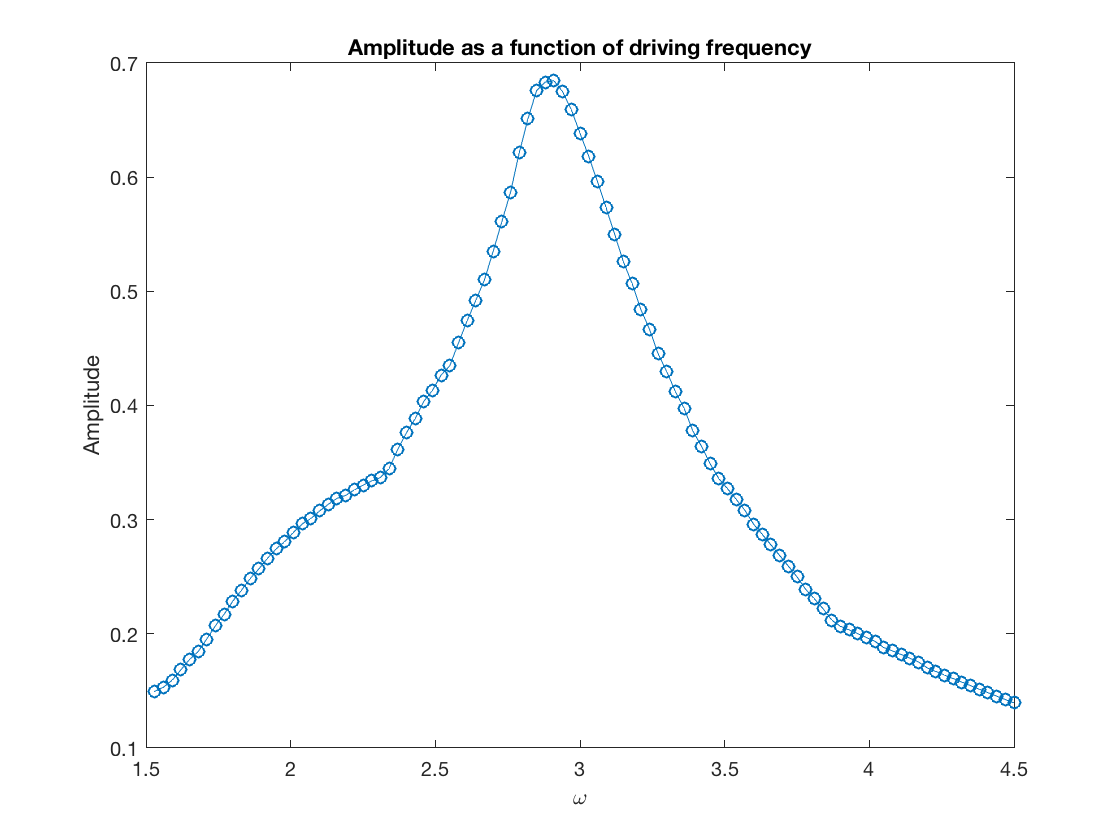

for i=1:100
    ome(i)=3/100*i+1.5;
    [t,w]=pendulum4(R,theta0,thetad0,gamma,ome(i));
     ind5 = find(w(:,2)>=0 & circshift(w(:,2), [-1 0]) <=0);
     A(i)=max(w(ind5,1));
     ind5=zeros;
end
plot(ome,A,'-o')
xlabel('\omega')
ylabel('Amplitude')
title('Amplitude as a function of driving frequency')

[Amax,nn]=max(A);
Amax

Amax = 0.6845

wmax=ome(nn)

wmax = 2.9100

(a) graph 1 showed us the amplitude of the steady state motion as a function of drving frequency. To make it smooth, more data are tested, the result is shown in graph 2. wmax is close to the natural frequency but still slightly smaller. 

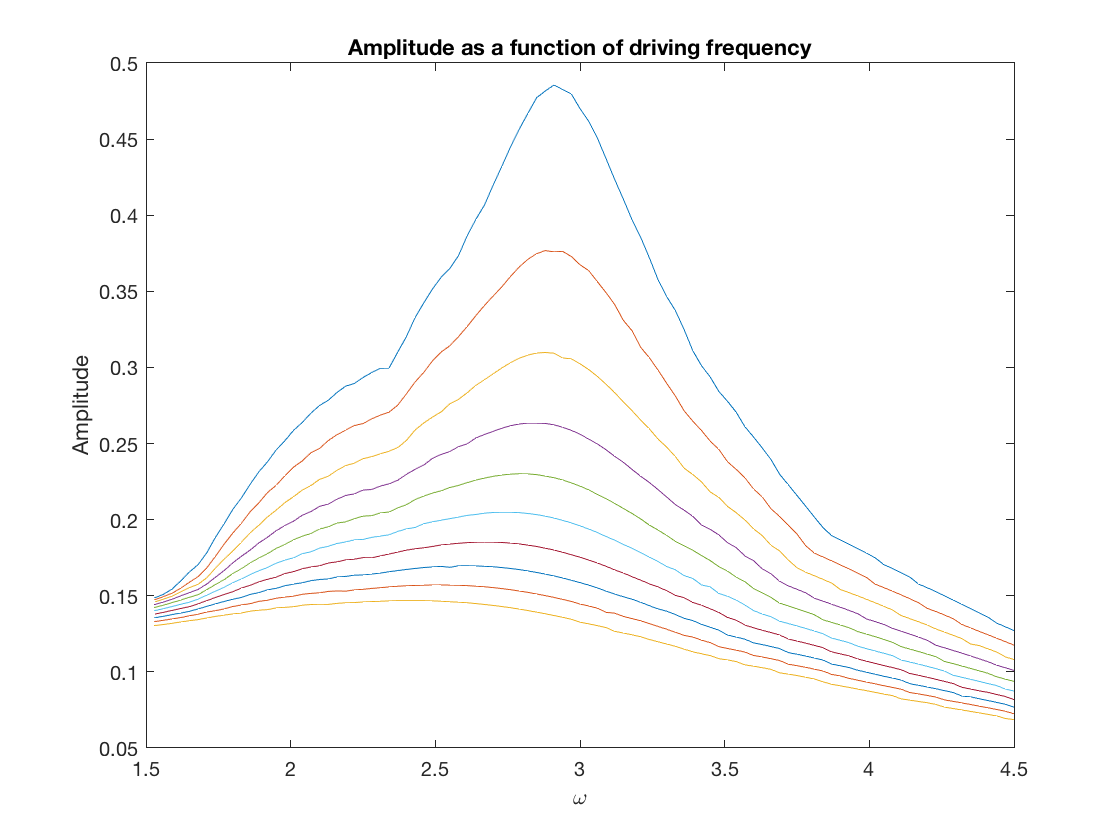

for j=1:10
    gamma(j)=j/5+0.5;
    for i=1:100  
    ome(i)=3/100*i+1.5;
    [t,w]=pendulum4(R,theta0,thetad0,gamma(j),ome(i));
     ind5 = find(w(:,2)>=0 & circshift(w(:,2), [-1 0]) <=0);
     A(i)=max(w(ind5,1));
     ind5=zeros;
    end
    plot(ome,A)
    xlabel('\omega')
    ylabel('Amplitude')
    title('Amplitude as a function of driving frequency')
    hold on
    [Amax(j),nn(j)]=max(A);
    wmax(j)=ome(nn(j));
    [dd2(j),n2(j)]=min(abs(A(nn(j):end)-(1/sqrt(2))*Amax(j)));
    [dd1(j),n1(j)]=min(abs(A(1:nn(j))-(1/sqrt(2))*Amax(j)));
    deltaw(j)=ome(n2(j)+nn(j)-1)-ome(n1(j));
    ome=zeros;
    A=zeros;
end
hold off

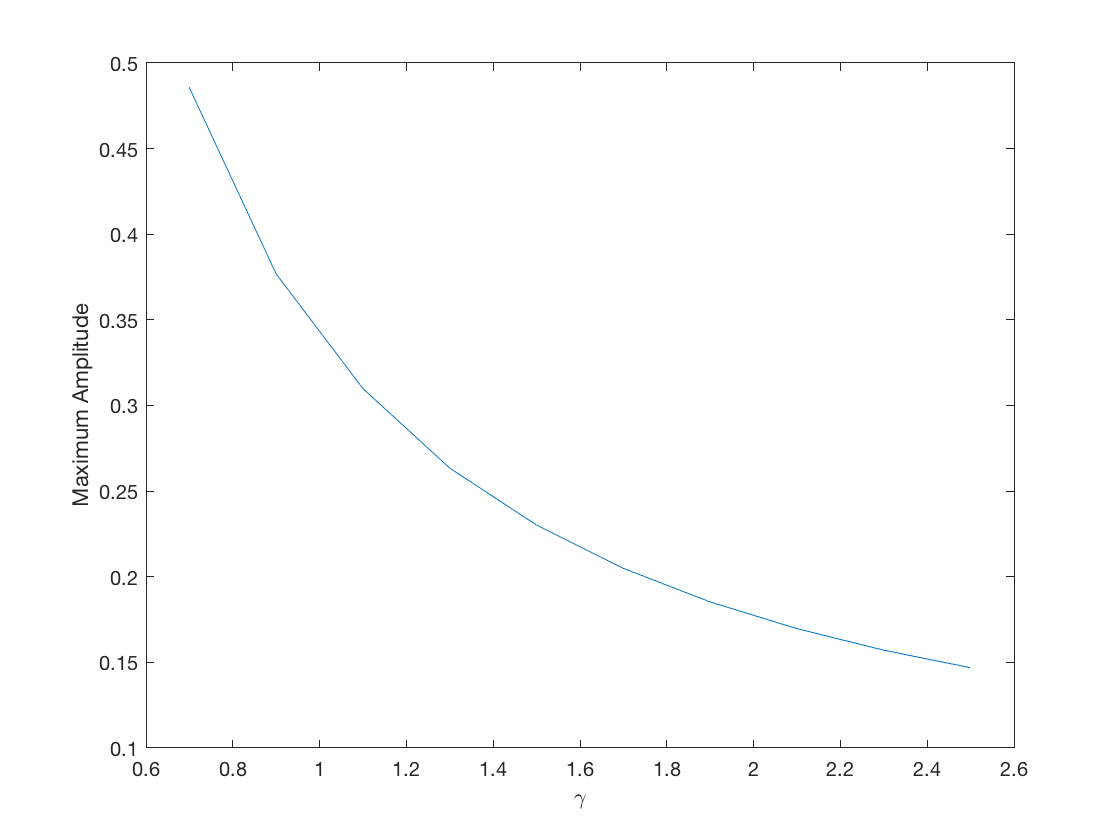

plot(gamma,Amax)
xlabel('\gamma')
ylabel('Maximum Amplitude')

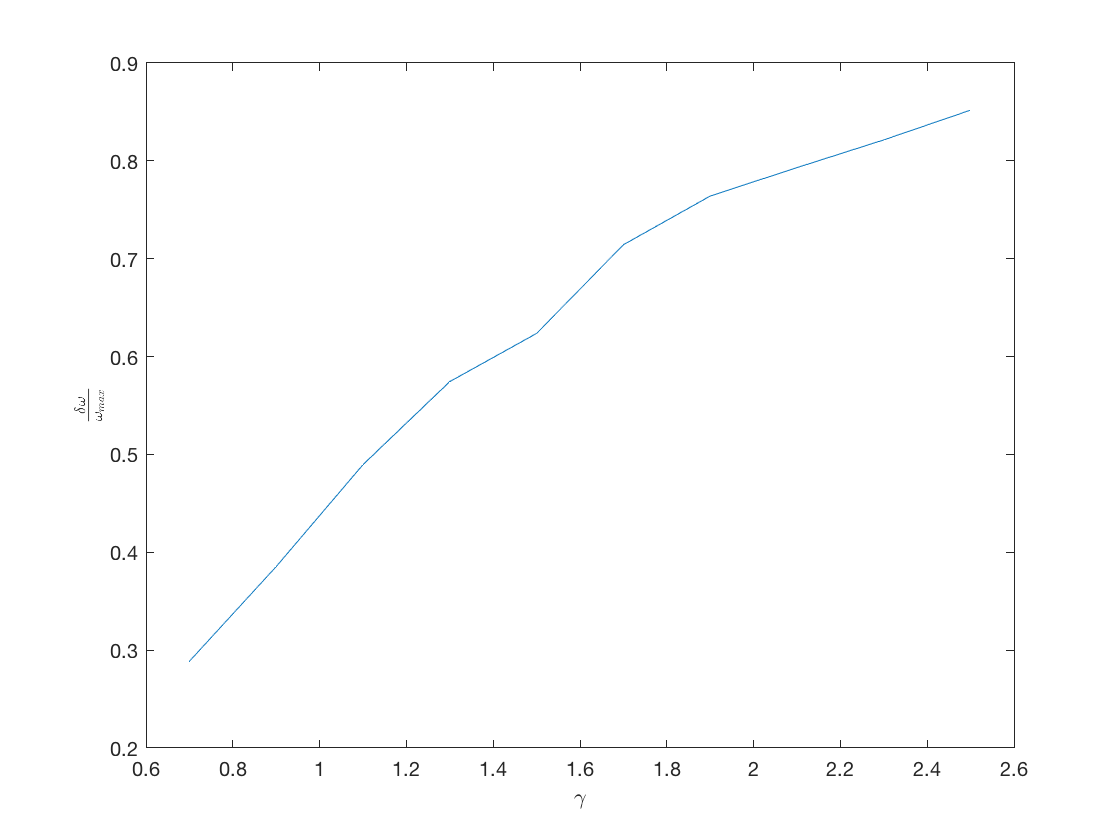

plot(gamma,deltaw./wmax)
xlabel('\gamma')
ylabel('$\frac{\delta\omega}{\omega_{max}}$','interpreter','latex')

(b) The maximum amplitude would be decrease with the damping constant while the ratio between �the width of resonance and w_max would increase with the damping constant.